## ROUTE MAPPING

close all 
clc
clear all

% Open the framnes mountains map
figure;
image = imread('Framnes_mapping.tif'); % Specify the path to the picture
imshow(image);

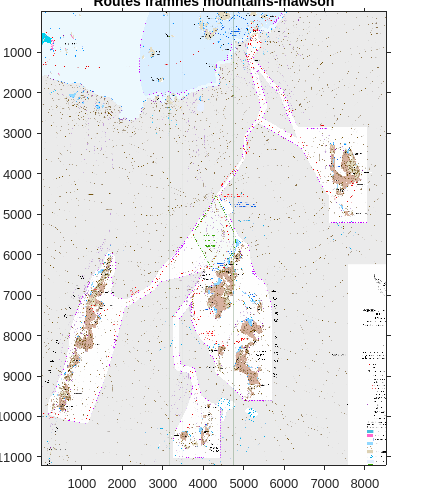

title('Routes framnes mountains-mawson');

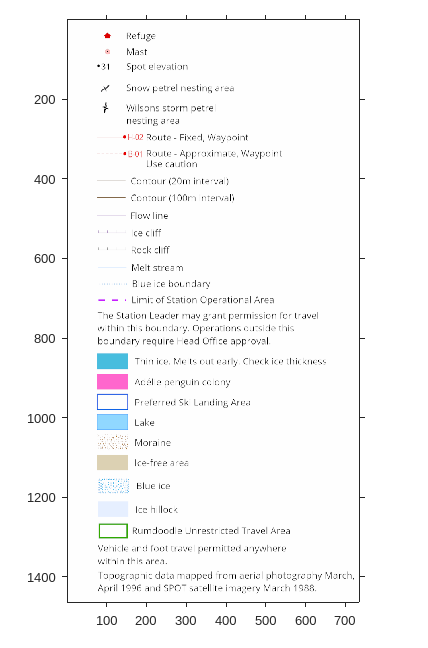


% Create another figure for the legend
figure;
legend = imread('Legend.png');
imshow(legend);

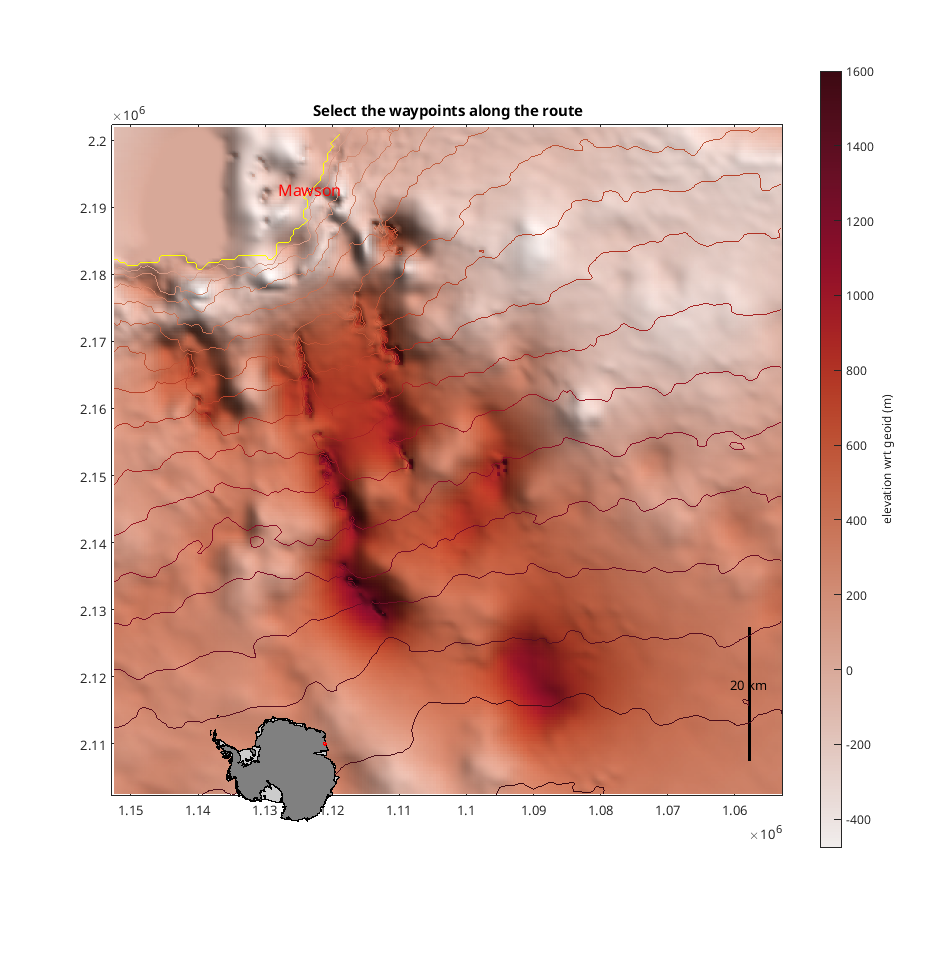


% Get coordinates of Mawson Station
Mawson_coords = scarloc('mawson station');
Spatial_res = 1;

% Create the map figure
figure('Position', [100, 100, 1200, 800]);

% Plot the map with Mawson Station and bedmachine data
mapzoomps(Mawson_coords(1)-0.4, Mawson_coords(2), 'size', [100 100], 'frame', 'off');
hold on;
scatterps(Mawson_coords(1), Mawson_coords(2), 10);
scarlabel('Mawson','fontsize',12,'color','r');
title('Select the waypoints along the route');
box on;
scalebarps;

% get bed and geo data
[bed,lat,lon] = bedmachine_data('bed',xlim,ylim,'geo');

% plotting stuff
pcolorps(lat, lon, bed);
cmocean('amp');       % optional colormap
bedmachine('surface','contour',0:100:3000);
cb = colorbar;
shadem([225 60],3);
ylabel(cb,'elevation wrt geoid (m)');
bedmachine('coast','y');
mapzoomps('sw','frame','off');
view([-90, 90]);

% Waypoints are selected
[lat, lon] = coord;

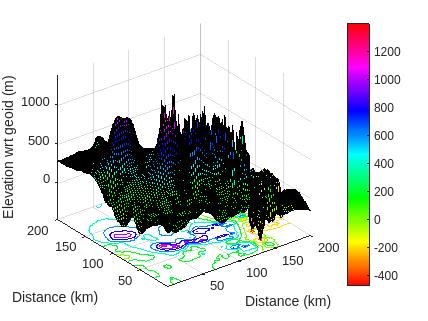


% 3d mesh plot
figure;
surf_mesh = surfc(bed);
colormap hsv;
xlabel('Distance (km)');
ylabel('Distance (km)');
zlabel('Elevation wrt geoid (m)')
colorbar;



% Assign start and end points
startlat = lat(1);
startlon = lon(1);
endlat = lat(end);
endlon = lon(end);
intermediatewaypoints = [lat(2:end-1) lon(2:end-1)];
waypoints = [startlat startlon; intermediatewaypoints; endlat endlon];
[lati,loni] = pspath([startlat endlat],[startlon endlon],Spatial_res);  %gives interpolated points between the specified waypoints
linpath = [lati ; loni]';       
path = [startlat,startlon];

% Initialize cell arrays to store latitude and longitude
path_lat = startlat;
path_lon = startlon;

for k = 1:height(waypoints)
    if k < height(waypoints)
        [interlat, interlon] = pspath([waypoints(k,1) waypoints(k+1,1)], [waypoints(k,2) waypoints(k+1,2)], Spatial_res);

        % Append new latitude and longitude values
        path_lat = [path_lat; interlat'];
        path_lon = [path_lon; interlon'];
    end
end

% Concatenate latitude and longitude arrays
path = [path_lat, path_lon];

d = pathdistps(path(:,1)', path(:,2)', 'km')';
z = bedmachine_interp('surface', path(:,1)', path(:,2)')';
d_meters = d*1000;  % Convert kilometers to meters

## SLICER FUNCTION AND VELOCITY PROFILER

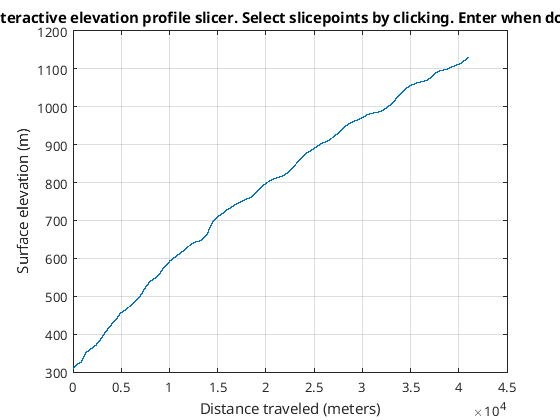

% Subplot 4: Interactive Elevation Profile Slicer
figure
plot(d_meters, z)
xlabel 'Distance traveled (meters)'
ylabel 'Surface elevation (m)'
grid on;

title('Interactive elevation profile slicer. Select slicepoints by clicking. Enter when done :)');
[slicepoints_x, ~] = ginput();

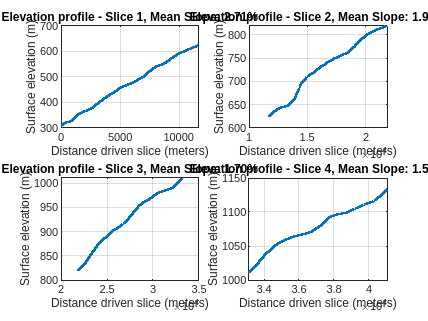

endslice_x = d_meters(end);
endslice_y = z(end);

num_slices = length(slicepoints_x) + 1;

% Calculate the number of rows and columns for the subplot grid
cols = ceil(sqrt(num_slices));
rows = ceil(num_slices / cols);

% Create a figure with a subplot grid and store slice-specific data
figure;
slice_data = cell(num_slices, 2);
mean_slopes = zeros(num_slices, 1);  % Store slopes in a column vector
for i = 1:num_slices
    if i == 1
        % for the first slice, start from the real distance
        start_distance = 0;
    else
        % for subsequent slices, start from the end of the previous slice
        start_distance = slice_data{i-1, 1}(end);
    end
    
    % handle the last slice differently
    if i == num_slices
        end_distance = endslice_x;
    else
        end_distance = slicepoints_x(i);
    end
    
    % find indices corresponding to the selected slice
    [~, start_index] = min(abs(d_meters - start_distance));
    [~, end_index] = min(abs(d_meters - end_distance));

    % Extract the elevation and distance data for the slice
    slice_data{i, 1} = d_meters(start_index:end_index);
    slice_data{i, 2} = z(start_index:end_index);

    % adjust distance to start from the real distance
    slice_data{i, 1} = slice_data{i, 1} - slice_data{i, 1}(1) + start_distance;

    % calculate the mean slope for the slice in percentage
    elevation_change = slice_data{i, 2}(end) - slice_data{i, 2}(1);
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    mean_slope = (elevation_change / distance_driven) * 100;
    mean_slopes(i) = mean_slope;  % Store mean slope in the column vector
    
    % calculate the subplot index based on the current iteration
    subplot(rows, cols, i);
    plot(slice_data{i, 1}, slice_data{i, 2}, 'LineWidth', 2);
    xlabel 'Distance driven slice (meters)'
    ylabel 'Surface elevation (m)'
    title(['Elevation profile - Slice ', num2str(i), ', Mean Slope: ', num2str(mean_slope, '%.2f'), '%']);
    grid on
end


slice_velocities = zeros(1, num_slices);
for i = 1:num_slices
    % prompt the user to enter the velocity profiles per slice, open to change
    prompt = ['Enter velocity for Slice ', num2str(i), ' (in km/h): '];
    slice_velocities(i) = input(prompt);
end


## timesim calcs

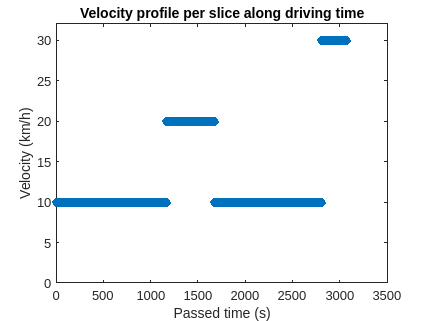

clear slice_times
slice_times = zeros(1, num_slices);
% ugly ass coding sorry
total_travel_time = 0;
for i = 1:num_slices
    distance_driven = slice_data{i, 1}(end) - slice_data{i, 1}(1);
    travel_time = distance_driven / slice_velocities(i);
    slice_times(i) = travel_time;
    total_travel_time = total_travel_time + travel_time;
end

% Ensure that total_travel_time is rounded up to the nearest integer
total_travel_time = ceil(total_travel_time);

% Adjust the creation of time_vector to accommodate the total travel time
time_vector = (1:1:total_travel_time)'; % remove the +2

vel_times = ones(length(time_vector), 1);
slope_times = ones(length(time_vector), 1);

current_time = 1; % Start from time 1
for i = 1:num_slices
    slice_duration = ceil(slice_times(i));
    slice_vel = slice_velocities(i);
    slice_slope = mean_slopes(i);
    
    % Ensure that the loop index doesn't exceed the length of vel_times and slope_times
    if current_time + slice_duration > total_travel_time
        slice_duration = total_travel_time - current_time + 1;
    end
    
    vel_times(current_time:current_time+slice_duration-1) = slice_vel;
    slope_times(current_time:current_time+slice_duration-1) = slice_slope;
    
    % Update the current time
    current_time = current_time + slice_duration;
end

velocity_profile = [time_vector, vel_times];
slope_profile = [time_vector, slope_times];

figure;
plot(time_vector,vel_times,'o')
ylim([0 max(slice_velocities)+2]);
ylabel('Velocity (km/h)');
xlabel('Passed time (s)');
title('Velocity profile per slice along driving time')


% Calculate total change in elevation
total_change_elevation = z(end) - z(1);

## Simulation parameters + Batt_mdens variation

T_start = 0.0;           % Simulation start time
T_stop = time_vector(end);  % Simulation end time (assuming time_vector is defined)
T_step = 1;               % Simulation timestep in seconds
Crr = 0.1;                % Rolling friction coefficient, not used currently

Mass_values = [400 500 600];        % Vehicle total mass
Battmassfrac = 0.3;       % Fraction of the total mass allocated to the battery

g = 9.81;                 % Gravitational acceleration
Batt_mdens_values = [80 150 200 250 300 400]; %Energy density of diff. configs (Wh/kg)
Packingfactor = 2;        % Offset to the energy density
Aux_power = 200; %Power draw used for non-drivetrain equipment (Watts)
kwh_used_values = zeros(numel(Mass_values)); 
SoC_values = zeros(numel(Mass_values)); % Preallocate matrix for efficiency
pground = 10000;  %Pascal, i.e. 10kPa or 0.1bar
D = 0.76;         %Tire diameter
b = 0.30;         %Tire width
n = 1;            %fitting constant characterising terrain (the exponent in the sinkage relations
k = 1000000;      %Pascal/m i.e 1MPa/m, 2nd fitting constant characterising the environment (the factor in front of the base of the exponent in the sinkage relation

for mass_idx = 1:numel(Mass_values)
    Mass = Mass_values(mass_idx);
    
    for batt_dens_idx = 1:numel(Batt_mdens_values)
        Batt_mdens = Batt_mdens_values(batt_dens_idx);
        
        % Run the simulation with current mass and battery mass fraction
        simOut = sim("Mass_est_rollfricimproved.slx", 'ExternalInput', num2str(Mass), 'ExternalInput', num2str(Batt_mdens));    
        
        % Store the simulation result
        kwh_used_values(mass_idx) = simOut.simout(end);
        SoC_values(batt_dens_idx,mass_idx) = simOut.simout1(end);
    
        disp(['Simulation completed for mass = ', num2str(Mass), ', Batt_mdens = ', num2str(Batt_mdens)]);
    end
end

Simulation completed for mass = 400, Batt_mdens = 80
Simulation completed for mass = 400, Batt_mdens = 150
Simulation completed for mass = 400, Batt_mdens = 200
Simulation completed for mass = 400, Batt_mdens = 250
Simulation completed for mass = 400, Batt_mdens = 300
Simulation completed for mass = 400, Batt_mdens = 400
Simulation completed for mass = 500, Batt_mdens = 80
Simulation completed for mass = 500, Batt_mdens = 150
Simulation completed for mass = 500, Batt_mdens = 200
Simulation completed for mass = 500, Batt_mdens = 250
Simulation completed for mass = 500, Batt_mdens = 300
Simulation completed for mass = 500, Batt_mdens = 400
Simulation completed for mass = 600, Batt_mdens = 80
Simulation completed for mass = 600, Batt_mdens = 150
Simulation completed for mass = 600, Batt_mdens = 200
Simulation completed for mass = 600, Batt_mdens = 250
Simulation completed for mass = 600, Batt_mdens = 300
Simulation completed for mass = 600, Batt_mdens = 400


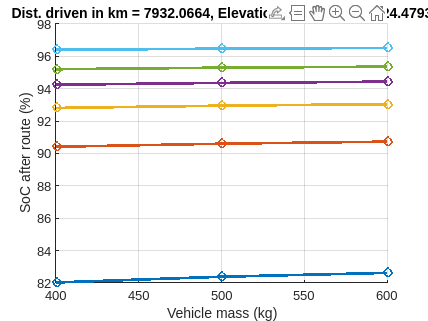


figure;

hold on; 

for batt_dens_idx = 1:numel(Batt_mdens_values)
    plot(Mass_values, SoC_values(batt_dens_idx, :), 'o-', 'LineWidth', 2, 'DisplayName', ['Batt density = ' num2str(Batt_mdens_values(batt_dens_idx))]);
end

xlabel('Vehicle mass (kg)');
ylabel('SoC after route (%)');
grid on;
title(['Dist. driven in m = ', num2str(distance_driven), ', Elevation change in m: ', num2str(total_change_elevation)]);

legend('show');

hold off;

## Simulation parameters + Batt_mfrac variation

T_start = 0.0;           % Simulation start time
T_stop = time_vector(end);  % Simulation end time (assuming time_vector is defined)

The end operator must be used within an array index expression.

T_step = 1;               % Simulation timestep in seconds
Crr = 0.1;                % Rolling friction coefficient, not used currently

Mass_values = [100 200 300 400 500 600 700 800];        % Vehicle total mass
Battmassfrac_values = 0.1:0.05:0.5;       % Fraction of the total mass allocated to the battery
g = 9.81;                 % Gravitational acceleration
Batt_mdens_values = 200; %Energy density of diff. configs (Wh/kg)
Packingfactor = 2;        % Offset to the energy density
Aux_power = 200; %Power draw used for non-drivetrain equipment (Watts)
kwh_used_values, SoC_values = zeros(numel(Mass_values)); % Preallocate matrix for efficiency

for mass_idx = 1:numel(Mass_values)
    Mass = Mass_values(mass_idx);
    
    for batt_mfrac_idx = 1:numel(Battmassfrac_values)
        Batt_mfrac = Battmassfrac_values(batt_mfrac_idx);
        
        % Run the simulation with current mass and battery mass fraction
        simOut = sim("Mass_est_rollfricimproved.slx", 'ExternalInput', num2str(Mass), 'ExternalInput', num2str(Battmassfrac));    
        
        % Store the simulation result
        kwh_used_values(mass_idx) = simOut.simout(end);
        SoC_values(batt_mfrac_idx,mass_idx) = simOut.simout1(end);
    
        disp(['Simulation completed for mass = ', num2str(Mass), ', Batt_mfrac = ', num2str(Batt_mfrac)]);
    end
end

figure;

hold on; 

for batt_mfrac_idx = 1:numel(Battmassfrac_values)
    plot(Mass_values, SoC_values(batt_mfrac_idx, :), 'o-', 'LineWidth', 2, 'DisplayName', ['Batt density = ' num2str(Batt_mdens_values(batt_mfrac_idx))]);
end

xlabel('Vehicle mass (kg)');
ylabel('SoC after route (%)');
grid on;
title(['Dist. driven in km = ', num2str(distance_driven), ', Elevation change in m: ', num2str(total_change_elevation)]);

legend('show');

hold off;